# **PD：Simple FCN**

# **PA1：CNN**

# **PA2：CNN**

# **PA3：CNN**

# **PA4：CNN**

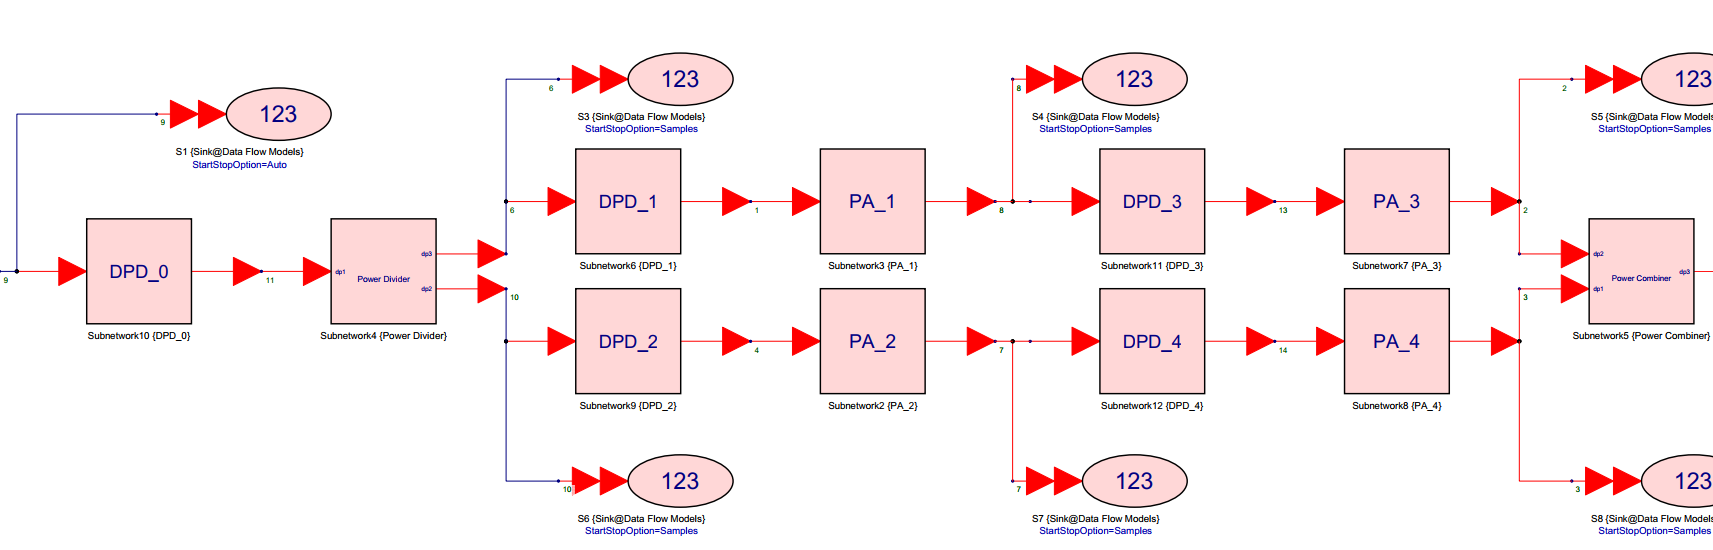

% 运行前请先将子文件夹添加到路径
clc;

## -----------------------------Original System----------------------------

此模型是完全固定的！

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);
Original_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end);
% 模型仿真
[U1,D1]=Power_Divider(Sys_input);
U2=PA_1(U1);
U3=PA_3(U2);
D2=PA_2(D1);
D3=PA_4(D2);
Original_output_sim=Power_Combiner(U3,D3);
% 性能评估
err=abs(Original_output_sim-Original_output) %模型本身的误差

err = 1.0e-13 *

    0.0037
    0.0030
    0.0057
    0.0049
    0.0051
    0.0050
    0.0098
    0.0063
    0.0109
    0.0111


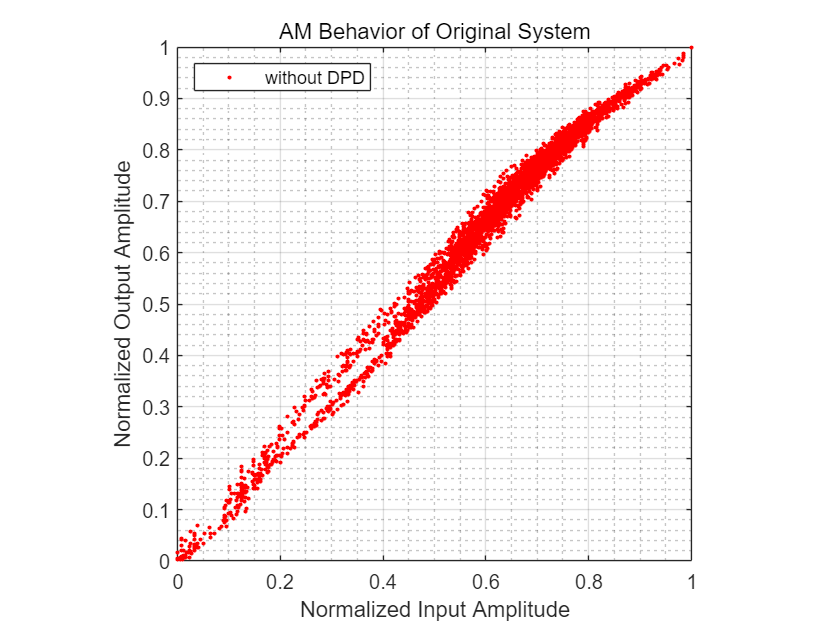

Plot_AM(Sys_input,Original_output_sim,'AM Behavior of Original System','without DPD');

nmse_sim= NMSE_dB(Sys_input,Original_output_sim);
nmse_act = NMSE_dB(Sys_input,Original_output);
fprintf('不使用DPD，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

不使用DPD，系统的NMSE仿真结果为 -16.688242 dB


fprintf('不使用DPD，系统的NMSE实测结果为 %f dB\n', nmse_act);

不使用DPD，系统的NMSE实测结果为 -16.688242 dB


## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);

## 训练PA1

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　　０．７５　｜　　　　　　０．５４　｜　　０．２８４７　｜　０．１４４９　｜　　０．００３０　｜
｜　　８０　｜　　　８０　｜　　　　　００：００：０２　｜　　　　　　　０．０５　｜　　　　　　０．０５　｜　　０．００１２　｜　０．００１５　｜　　０．００３０　｜
｜　１６０　｜　　１６０　｜　　　　　００：００：０３　｜　　　　　　　０．０４　｜　　　　　　０．０４　｜　　０．０００６　｜　０．００１０　｜　　０．００３０　｜
｜　２４０　｜　　２４０　｜　　　　　００：００：０４　｜　　　　　　　０．０４　｜　　　　　　０．０５　｜　　０．０００９　｜　０．００１０　｜　　０．００３０　｜
｜　３２０　｜　　３２０　｜　　　　　００：００：０６　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００５　｜　０．０００８　｜　　０．００３０　｜
｜　４００　｜　　４００　｜　　　　　００：００：０７　｜　　　　　　　０．０３　｜　　　　　　０．０５　｜　　０．０００４　｜　０．００１１　｜　　０．００３０　｜
｜　４８０　｜　　４８０　｜　　　　　００：００：０８　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００３　｜　０．０００９　｜　　０．００３０　｜
｜　５６０　｜　　５６０　｜　　　　　００：００：０９　｜　　　　　　　０．０２　｜　　　　　　０．０４　｜　　０．０００２　｜　０．０００９　｜　　０

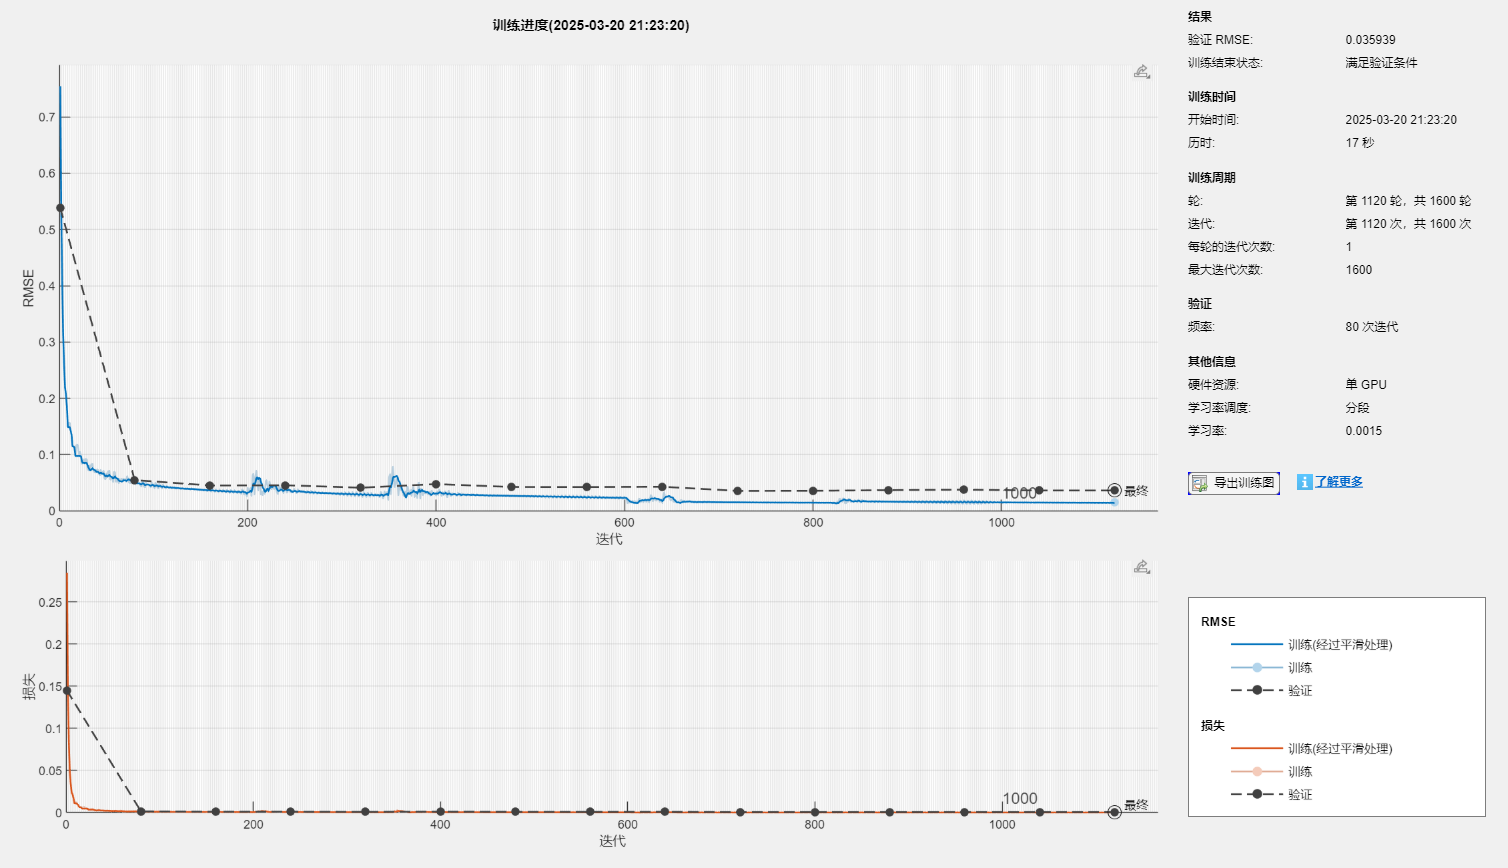

PA1_x_i=Data_matrix(:,3);PA1_x_q=Data_matrix(:,4);
PA1_y_i=Data_matrix(:,7);PA1_y_q=Data_matrix(:,8);

M=7; % Memory Depth
CNN=CNN_train(PA1_x_i,PA1_x_q,PA1_y_i,PA1_y_q,M);

save('Algorithm_B\Alg_PA1.mat', 'CNN','-append');

## 训练PA2

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　　０．６２　｜　　　　　　０．４５　｜　　０．１９３０　｜　０．１０３０　｜　　０．００３０　｜
｜　　８０　｜　　　８０　｜　　　　　００：００：０２　｜　　　　　　　０．０５　｜　　　　　　０．０７　｜　　０．００１１　｜　０．００２４　｜　　０．００３０　｜
｜　１６０　｜　　１６０　｜　　　　　００：００：０３　｜　　　　　　　０．０３　｜　　　　　　０．０５　｜　　０．０００５　｜　０．００１２　｜　　０．００３０　｜
｜　２４０　｜　　２４０　｜　　　　　００：００：０４　｜　　　　　　　０．０４　｜　　　　　　０．０６　｜　　０．０００７　｜　０．００１８　｜　　０．００３０　｜
｜　３２０　｜　　３２０　｜　　　　　００：００：０５　｜　　　　　　　０．０３　｜　　　　　　０．０５　｜　　０．０００４　｜　０．００１０　｜　　０．００３０　｜
｜　４００　｜　　４００　｜　　　　　００：００：０６　｜　　　　　　　０．０２　｜　　　　　　０．０４　｜　　０．０００３　｜　０．０００９　｜　　０．００３０　｜
｜　４８０　｜　　４８０　｜　　　　　００：００：０８　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００３　｜　０．０００８　｜　　０．００３０　｜
｜　５６０　｜　　５６０　｜　　　　　００：００：０９　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００５　｜　０．００１０　｜　　０

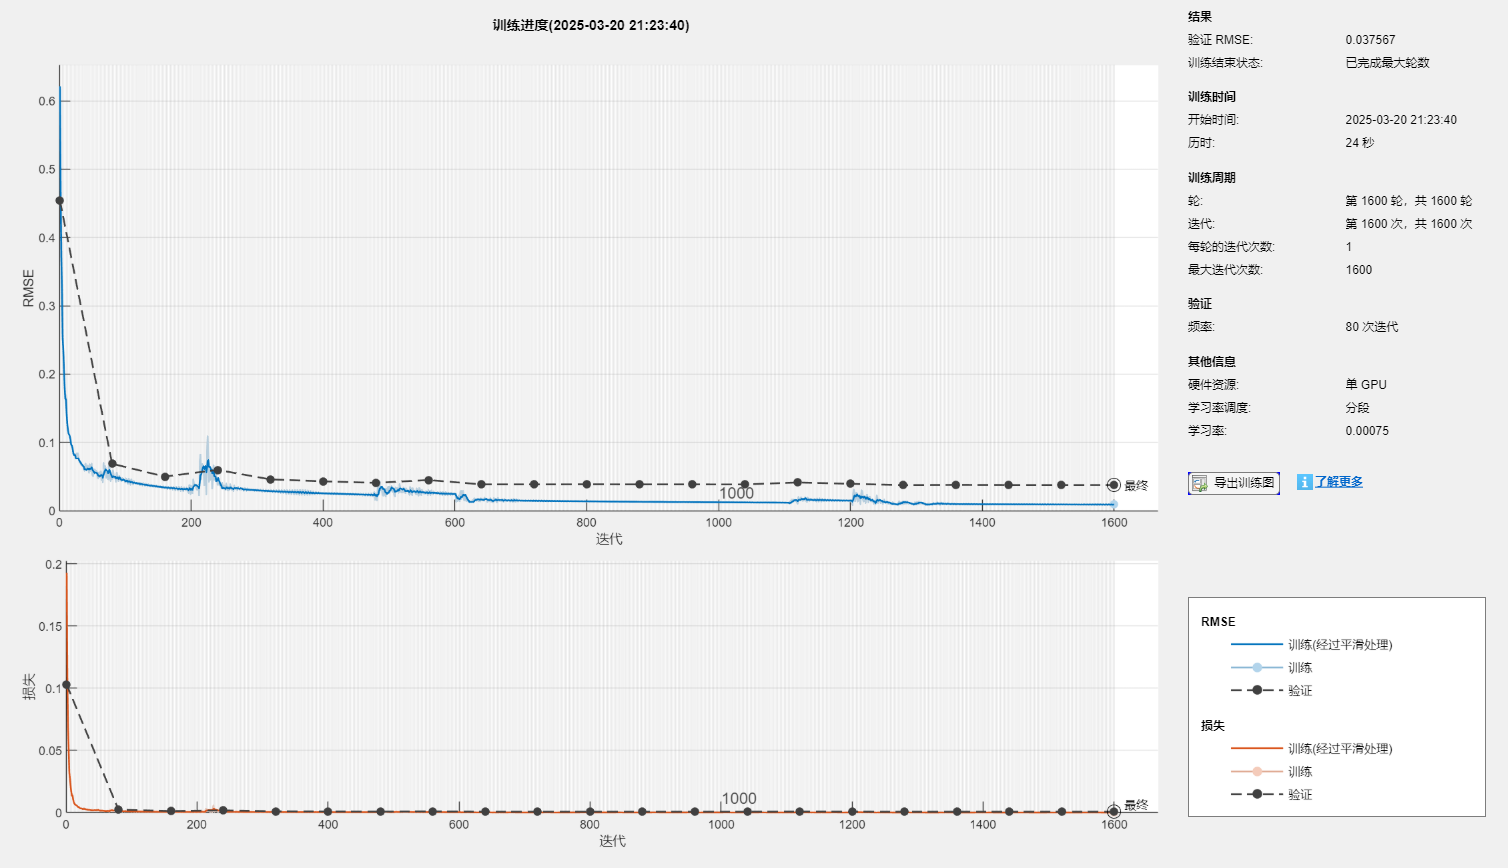

% 根据需要选取原始数据
PA2_x_i=Data_matrix(:,5);PA2_x_q=Data_matrix(:,6);
PA2_y_i=Data_matrix(:,9);PA2_y_q=Data_matrix(:,10);

CNN=CNN_train(PA2_x_i,PA2_x_q,PA2_y_i,PA2_y_q,M);

save('Algorithm_B\Alg_PA2.mat', 'CNN','-append');

## 第一次模拟迭代（为训练PA3和PA4）

[S_U1,S_D1]=Power_Divider(Sys_input);
S_U1_DPD= DPD(S_U1,M,5,'Algorithm_B\Alg_PA1.mat');% input,记忆深度,不同算法,不同位置
S_U2    = PA_1(S_U1_DPD);
S_U3    = PA_3(S_U2);
S_D1_DPD= DPD(S_D1,M,5,'Algorithm_B\Alg_PA1.mat');% input,记忆深度,不同算法,不同位置
S_D2    = PA_2(S_D1_DPD);
S_D3    = PA_4(S_D2);

## 训练PA3

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　　０．７４　｜　　　　　　０．５６　｜　　０．２７４０　｜　０．１５６２　｜　　０．００３０　｜
｜　　８０　｜　　　８０　｜　　　　　００：００：０２　｜　　　　　　　０．０５　｜　　　　　　０．０６　｜　　０．００１２　｜　０．００１５　｜　　０．００３０　｜
｜　１６０　｜　　１６０　｜　　　　　００：００：０３　｜　　　　　　　０．０４　｜　　　　　　０．０５　｜　　０．０００７　｜　０．００１０　｜　　０．００３０　｜
｜　２４０　｜　　２４０　｜　　　　　００：００：０４　｜　　　　　　　０．０４　｜　　　　　　０．０４　｜　　０．０００７　｜　０．０００８　｜　　０．００３０　｜
｜　３２０　｜　　３２０　｜　　　　　００：００：０５　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００４　｜　０．０００７　｜　　０．００３０　｜
｜　４００　｜　　４００　｜　　　　　００：００：０７　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００５　｜　０．０００８　｜　　０．００３０　｜
｜　４８０　｜　　４８０　｜　　　　　００：００：０８　｜　　　　　　　０．０３　｜　　　　　　０．０５　｜　　０．０００５　｜　０．００１２　｜　　０．００３０　｜
｜　５６０　｜　　５６０　｜　　　　　００：００：０９　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００４　｜　０．０００８　｜　　０

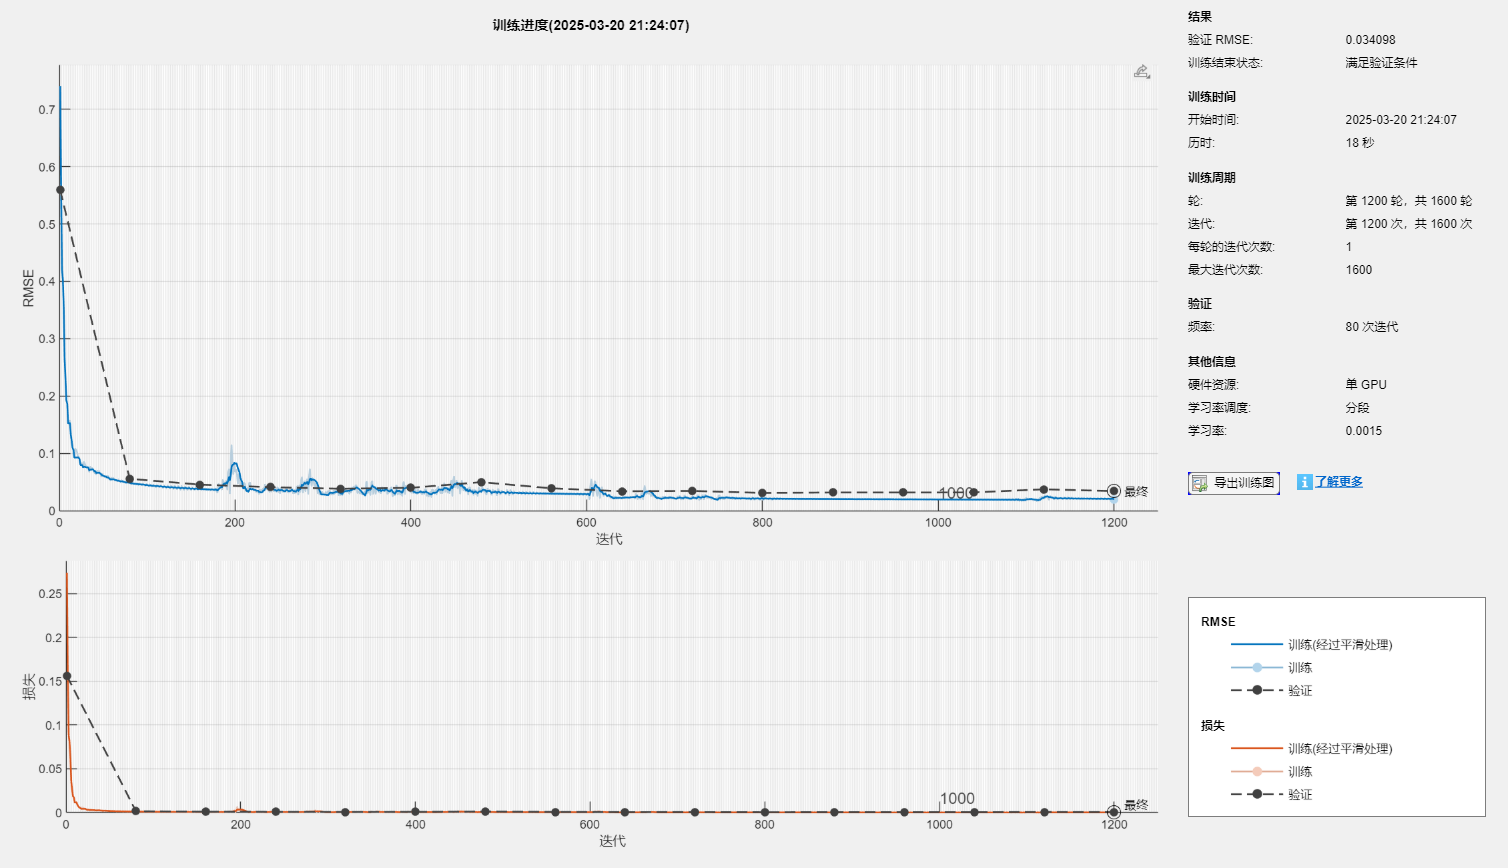

PA3_x_i=real(S_U2);PA3_x_q=imag(S_U2);
PA3_y_i=real(S_U3);PA3_y_q=imag(S_U3);

CNN=CNN_train(PA3_x_i,PA3_x_q,PA3_y_i,PA3_y_q,M);

save('Algorithm_B\Alg_PA3.mat', 'CNN','-append');

## 训练PA4

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　　０．６７　｜　　　　　　０．５０　｜　　０．２２１２　｜　０．１２４７　｜　　０．００３０　｜
｜　　８０　｜　　　８０　｜　　　　　００：００：０２　｜　　　　　　　０．０５　｜　　　　　　０．０６　｜　　０．００１５　｜　０．００１６　｜　　０．００３０　｜
｜　１６０　｜　　１６０　｜　　　　　００：００：０３　｜　　　　　　　０．０４　｜　　　　　　０．０４　｜　　０．０００８　｜　０．００１０　｜　　０．００３０　｜
｜　２４０　｜　　２４０　｜　　　　　００：００：０５　｜　　　　　　　０．０３　｜　　　　　　０．０５　｜　　０．０００６　｜　０．００１１　｜　　０．００３０　｜
｜　３２０　｜　　３２０　｜　　　　　００：００：０６　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００４　｜　０．０００９　｜　　０．００３０　｜
｜　４００　｜　　４００　｜　　　　　００：００：０７　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００５　｜　０．０００７　｜　　０．００３０　｜
｜　４８０　｜　　４８０　｜　　　　　００：００：０８　｜　　　　　　　０．０３　｜　　　　　　０．０４　｜　　０．０００４　｜　０．０００７　｜　　０．００３０　｜
｜　５６０　｜　　５６０　｜　　　　　００：００：０９　｜　　　　　　　０．０４　｜　　　　　　０．０４　｜　　０．０００６　｜　０．０００８　｜　　０

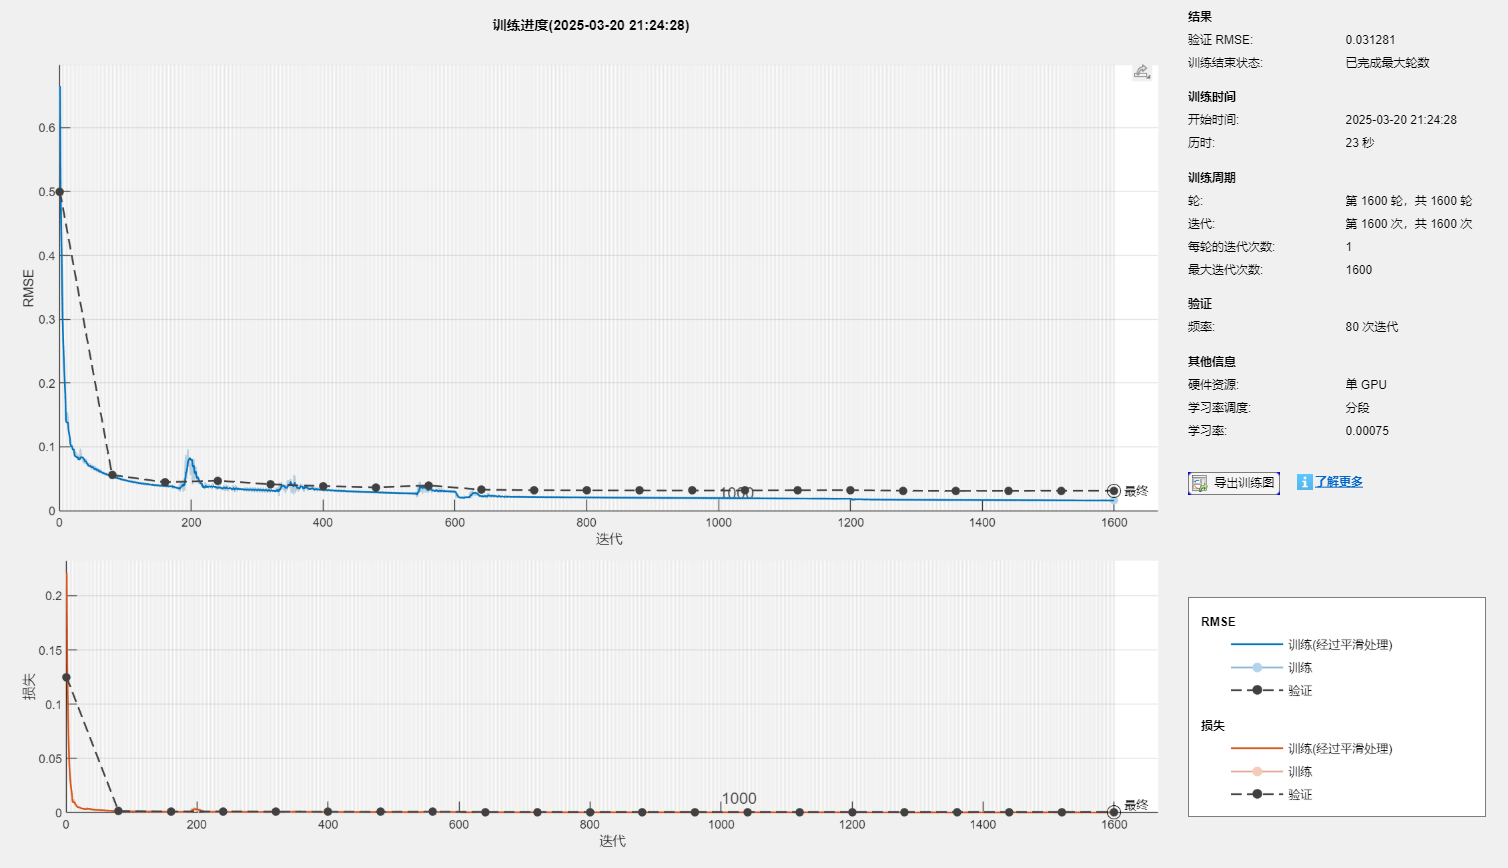

PA4_x_i=real(S_D2);PA4_x_q=imag(S_D2);
PA4_y_i=real(S_D3);PA4_y_q=imag(S_D3);

CNN=CNN_train(PA4_x_i,PA4_x_q,PA4_y_i,PA4_y_q,M);

save('Algorithm_B\Alg_PA4.mat', 'CNN','-append');

## 第二次模拟迭代（为训练PD）

[S_U1,S_D1]=Power_Divider(Sys_input);
S_U1_DPD= DPD(S_U1,M,5,'Algorithm_B\Alg_PA1.mat');% input,记忆深度,不同算法,不同位置
S_U2    = PA_1(S_U1_DPD);
S_U2_DPD= DPD(S_U2,M,5,'Algorithm_B\Alg_PA3.mat');% input,记忆深度,不同算法,不同位置
S_U3    = PA_3(S_U2_DPD);
S_D1_DPD= DPD(S_D1,M,5,'Algorithm_B\Alg_PA2.mat');% input,记忆深度,不同算法,不同位置
S_D2    = PA_2(S_D1_DPD);
S_D2_DPD= DPD(S_D2,M,5,'Algorithm_B\Alg_PA4.mat');% input,记忆深度,不同算法,不同位置
S_D3    = PA_4(S_D2_DPD);
Sys_output_train=Power_Combiner(S_U3,S_D3);

## 训练PD

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　　１．３３　｜　　　　　　１．２６　｜　　０．８８４７　｜　０．７９４９　｜　　０．００３０　｜
｜　　８０　｜　　　８０　｜　　　　　００：００：０２　｜　　　　　　　０．１１　｜　　　　　　０．１２　｜　　０．００６５　｜　０．００６８　｜　　０．００３０　｜
｜　１６０　｜　　１６０　｜　　　　　００：００：０３　｜　　　　　　　０．０８　｜　　　　　　０．０８　｜　　０．００２８　｜　０．００３５　｜　　０．００３０　｜
｜　２４０　｜　　２４０　｜　　　　　００：００：０４　｜　　　　　　　０．０７　｜　　　　　　０．０８　｜　　０．００２４　｜　０．００３２　｜　　０．００３０　｜
｜　３２０　｜　　３２０　｜　　　　　００：００：０６　｜　　　　　　　０．０６　｜　　　　　　０．０７　｜　　０．００１８　｜　０．００２６　｜　　０．００３０　｜
｜　４００　｜　　４００　｜　　　　　００：００：０７　｜　　　　　　　０．０８　｜　　　　　　０．０８　｜　　０．００３１　｜　０．００３２　｜　　０．００３０　｜
｜　４８０　｜　　４８０　｜　　　　　００：００：０８　｜　　　　　　　０．０６　｜　　　　　　０．０７　｜　　０．００２０　｜　０．００２８　｜　　０．００３０　｜
｜　５６０　｜　　５６０　｜　　　　　００：００：０９　｜　　　　　　　０．０７　｜　　　　　　０．０８　｜　　０．００２５　｜　０．００３３　｜　　０

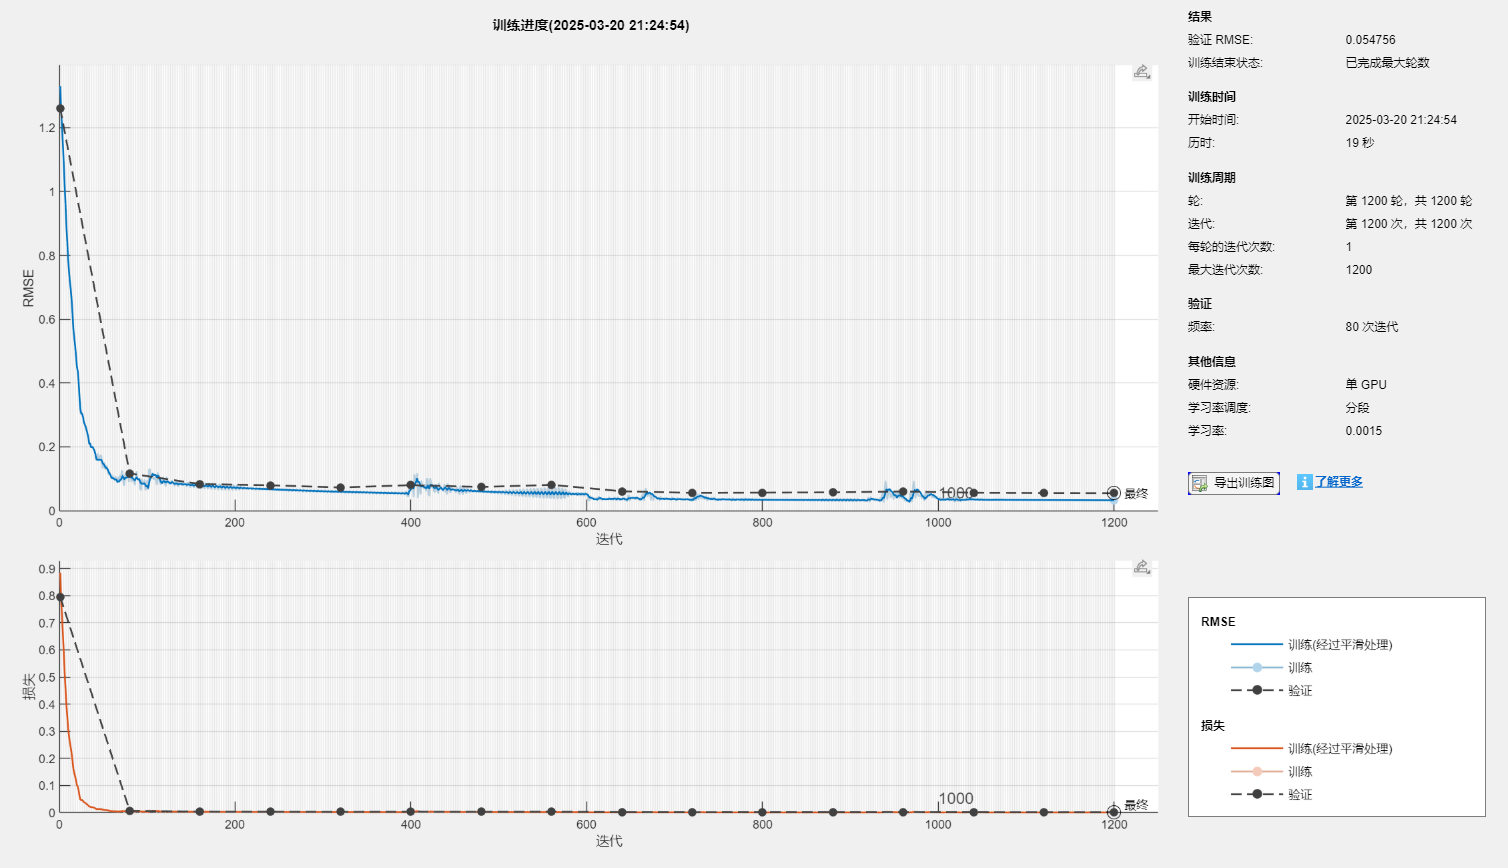

PD_x_i=real(Sys_input);PD_x_q=imag(Sys_input);
PD_y_i=real(Sys_output_train);PD_y_q=imag(Sys_output_train);

Simple_FCN=simpleFCN_train(PD_x_i,PD_x_q,PD_y_i,PD_y_q,M);

save('Algorithm_B\Alg_PD.mat', 'Simple_FCN','-append');

## 系统模拟

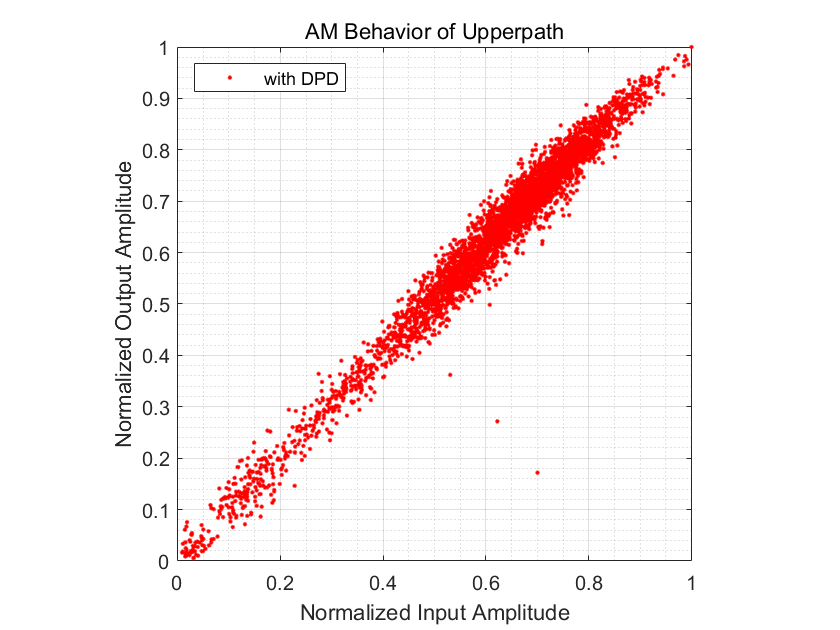

% 参数需要保持一致
M = 7;
Sys_input_DPD=DPD(Sys_input,M,10,'Algorithm_B\Alg_PD.mat');
[S_U1,S_D1]=Power_Divider(Sys_input_DPD);
S_U1_DPD= DPD(S_U1,M,5,'Algorithm_B\Alg_PA1.mat');% input,记忆深度,不同算法,不同位置
S_U2    = PA_1(S_U1_DPD);
S_U2_DPD= DPD(S_U2,M,5,'Algorithm_B\Alg_PA3.mat');% input,记忆深度,不同算法,不同位置
S_U3    = PA_3(S_U2_DPD);
S_D1_DPD= DPD(S_D1,M,5,'Algorithm_B\Alg_PA2.mat');% input,记忆深度,不同算法,不同位置
S_D2    = PA_2(S_D1_DPD);
S_D2_DPD= DPD(S_D2,M,5,'Algorithm_B\Alg_PA4.mat');% input,记忆深度,不同算法,不同位置
S_D3    = PA_4(S_D2_DPD);
Sys_output_sim=Power_Combiner(S_U3,S_D3);

% 性能评估
Plot_AM(S_U1,S_U3,'AM Behavior of Upperpath','with DPD');

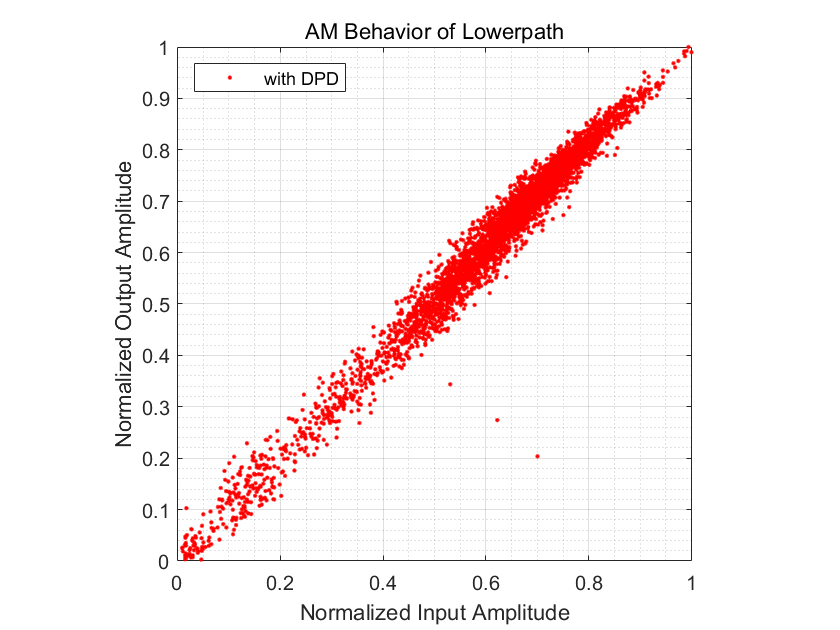

Plot_AM(S_D1,S_D3,'AM Behavior of Lowerpath','with DPD');

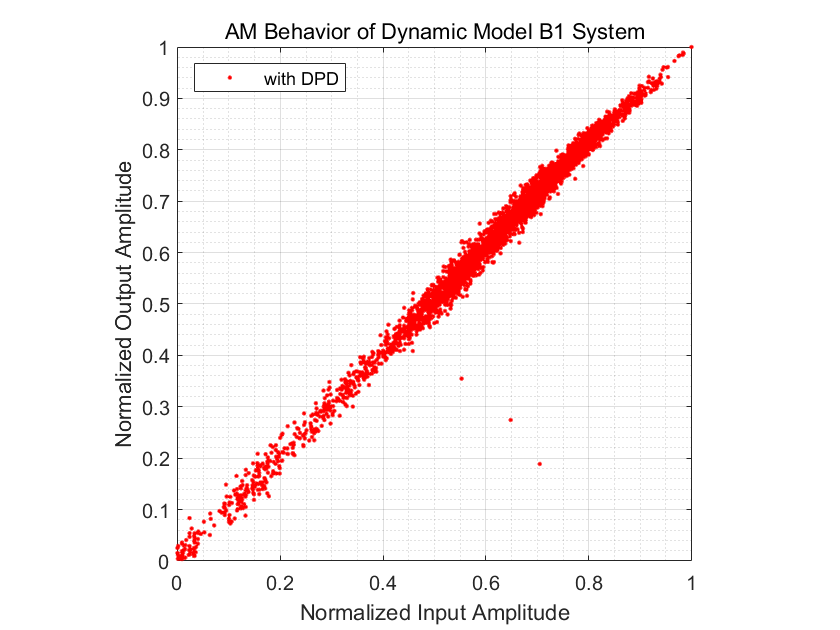

Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Dynamic Model B1 System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model B1，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model B1，系统的NMSE仿真结果为 -24.849735 dB
